# Regional Plots

Description: This algorithm plot  bar and box of mean and weighted mean capacity factor. Also it makes a table at the end to summarize the data.

Developed by Natanael Bolson

Supervised by Prof. Tad Patzek

Energy Geosystems Group -ANPERC - KAUST 11/2020

clc
clear 
close all
run CF_Calculation.mlx

## Color

% Colormap
Color=[85,200,60       % Biomass 0,104,55  
      55,55,55          % Fossil
      202,0,32          % Geothermal
      33,102,172        % Hydro
      128,115,172        % Nuclear
      255,199,44      % Solar 244,109,67 
      146,197,222]/255; % Wind 

% For the boxplot
ColorBR=flipud(Color); 

## Legends

% Legend Resources
legR={'$$\mathrm{Biomass}$$';'$$\mathrm{Fossil}$$';'$$\mathrm{Geoth.}$$';...
    '$$\mathrm{Hydro}$$';'$$\mathrm{Nuclear}$$';'$$\mathrm{Solar}$$';...
    '$$\mathrm{Wind}$$';};


## Africa

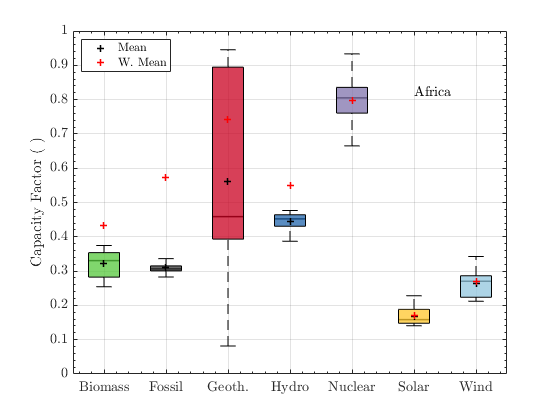

Africa_B=[Mat_CF_Bio(:,1) Mat_CF_Fos(:,1) Mat_CF_Geo(:,1) Mat_CF_Hyd(:,1)...
    Mat_CF_Nuc(:,1) Mat_CF_Sol(:,1) Mat_CF_Win(:,1)];
Africa_Mean_CF=[Mean_CF_Bio(1) Mean_CF_Fos(1) Mean_CF_Geo(1)...
    Mean_CF_Hyd(1) Mean_CF_Nuc(1) Mean_CF_Sol(1) Mean_CF_Win(1)];
Africa_Mean_CF_W=[Mean_CF_W_Bio(1) Mean_CF_W_Fos(1) Mean_CF_W_Geo(1)...
    Mean_CF_W_Hyd(1) Mean_CF_W_Nuc(1) Mean_CF_W_Sol(1) Mean_CF_W_Win(1)];
Africa_STD=[STD_CF_Bio(1) STD_CF_Fos(1) STD_CF_Geo(1) STD_CF_Hyd(1)...
    STD_CF_Nuc(1) STD_CF_Sol(1) STD_CF_Win(1)];

X=categorical(legR);

 
figure('Name','Box Africa')
hold on
plot(Africa_Mean_CF,'+k','LineWidth',1.5)
plot(Africa_Mean_CF_W,'+r','LineWidth',1.5)
boxplot(Africa_B,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorBR(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(Africa_Mean_CF,'+k','LineWidth',1.5)
plot(Africa_Mean_CF_W,'+r','LineWidth',1.5)
% xlabel('$$\mathrm{Source}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
legend({'Mean','W.~Mean'},'Location','northwest','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
text(6,0.82,'Africa','Fontsize',14,'Interpreter','latex')
ylim([0 1])
set(gca, 'XTickLabel', legR);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex') 
%   print('-dpdf','-r400','Africa_CF_B.pdf');
print('-dpng','-r400','Africa_CF_B.png');

## Asia

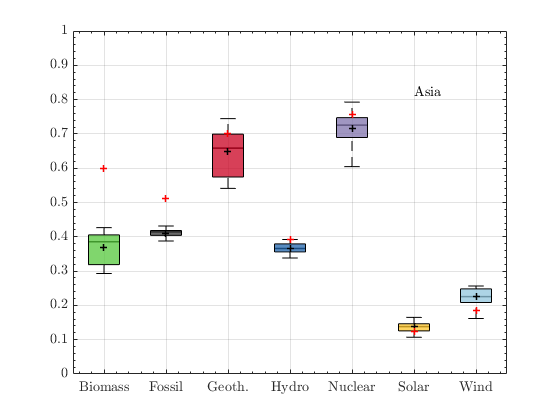

Asia_B=[Mat_CF_Bio(:,2) Mat_CF_Fos(:,2) Mat_CF_Geo(:,2) Mat_CF_Hyd(:,2)...
    Mat_CF_Nuc(:,2) Mat_CF_Sol(:,2) Mat_CF_Win(:,2)];
Asia_Mean_CF=[Mean_CF_Bio(2) Mean_CF_Fos(2) Mean_CF_Geo(2)...
    Mean_CF_Hyd(2) Mean_CF_Nuc(2) Mean_CF_Sol(2) Mean_CF_Win(2)];
Asia_Mean_CF_W=[Mean_CF_W_Bio(2) Mean_CF_W_Fos(2) Mean_CF_W_Geo(2)...
    Mean_CF_W_Hyd(2) Mean_CF_W_Nuc(2) Mean_CF_W_Sol(2) Mean_CF_W_Win(2)];
Asia_STD=[STD_CF_Bio(2) STD_CF_Fos(2) STD_CF_Geo(2) STD_CF_Hyd(2)...
    STD_CF_Nuc(2) STD_CF_Sol(2) STD_CF_Win(2)];



figure('Name','Box Asia')
hold on
plot(Asia_Mean_CF,'+k','LineWidth',1.5)
plot(Asia_Mean_CF_W,'+r','LineWidth',1.5)
boxplot(Asia_B,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorBR(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(Asia_Mean_CF,'+k','LineWidth',1.5)
plot(Asia_Mean_CF_W,'+r','LineWidth',1.5)
% xlabel('$$\mathrm{Source}$$','interpreter','latex')
%  ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
%  legend({'Mean','W.~Mean'},'Location','northwest','FontSize', 12,'NumColumns',1,...
%     'box','on','interpreter','latex')
text(6,0.82,'Asia','Fontsize',14,'Interpreter','latex')
ylim([0 1])
set(gca, 'XTickLabel', legR);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
%   print('-dpdf','-r400','Asia_CF_B.pdf');
 print('-dpng','-r400','Asia_CF_B.png');

## CIS

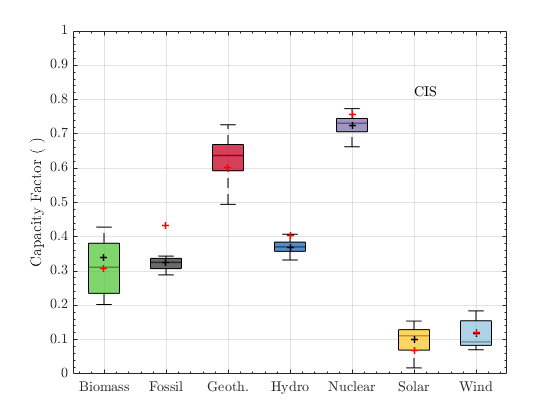

CIS_B=[Mat_CF_Bio(:,3) Mat_CF_Fos(:,3) Mat_CF_Geo(:,3) Mat_CF_Hyd(:,3)...
    Mat_CF_Nuc(:,3) Mat_CF_Sol(:,3) Mat_CF_Win(:,3)];
CIS_Mean_CF=[Mean_CF_Bio(3) Mean_CF_Fos(3) Mean_CF_Geo(3)...
    Mean_CF_Hyd(3) Mean_CF_Nuc(3) Mean_CF_Sol(3) Mean_CF_Win(3)];
CIS_Mean_CF_W=[Mean_CF_W_Bio(3) Mean_CF_W_Fos(3) Mean_CF_W_Geo(3)...
    Mean_CF_W_Hyd(3) Mean_CF_W_Nuc(3) Mean_CF_W_Sol(3) Mean_CF_W_Win(3)];
CIS_STD=[STD_CF_Bio(3) STD_CF_Fos(3) STD_CF_Geo(3) STD_CF_Hyd(3)...
    STD_CF_Nuc(3) STD_CF_Sol(3) STD_CF_Win(3)];



figure('Name','Box CIS')
hold on
plot(CIS_Mean_CF,'+k','LineWidth',1.5)
plot(CIS_Mean_CF_W,'+r','LineWidth',1.5)
boxplot(CIS_B,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorBR(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(CIS_Mean_CF,'+k','LineWidth',1.5)
plot(CIS_Mean_CF_W,'+r','LineWidth',1.5)
% xlabel('$$\mathrm{Source}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
% legend({'Mean','W.~Mean'},'Location','northeast','FontSize', 12,'NumColumns',1,...
%     'box','on','interpreter','latex')
text(6,0.82,'CIS','Fontsize',14,'Interpreter','latex')
ylim([0 1])
set(gca, 'XTickLabel', legR);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-dpdf','-r400','CIS_CF_B.pdf');
print('-dpng','-r400','CIS_CF_B.png');

## Europe

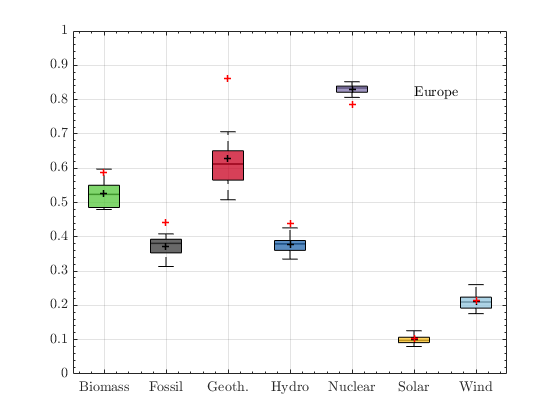

Europe_B=[Mat_CF_Bio(:,4) Mat_CF_Fos(:,4) Mat_CF_Geo(:,4) Mat_CF_Hyd(:,4)...
    Mat_CF_Nuc(:,4) Mat_CF_Sol(:,4) Mat_CF_Win(:,4)];
Europe_Mean_CF=[Mean_CF_Bio(4) Mean_CF_Fos(4) Mean_CF_Geo(4)...
    Mean_CF_Hyd(4) Mean_CF_Nuc(4) Mean_CF_Sol(4) Mean_CF_Win(4)];
Europe_Mean_CF_W=[Mean_CF_W_Bio(4) Mean_CF_W_Fos(4) Mean_CF_W_Geo(4)...
    Mean_CF_W_Hyd(4) Mean_CF_W_Nuc(4) Mean_CF_W_Sol(4) Mean_CF_W_Win(4)];
Europe_STD=[STD_CF_Bio(4) STD_CF_Fos(4) STD_CF_Geo(4) STD_CF_Hyd(4)...
    STD_CF_Nuc(4) STD_CF_Sol(4) STD_CF_Win(4)];



figure('Name','Box Europe')
hold on
plot(Europe_Mean_CF,'+k','LineWidth',1.5)
plot(Europe_Mean_CF_W,'+r','LineWidth',1.5)
boxplot(Europe_B,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorBR(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(Europe_Mean_CF,'+k','LineWidth',1.5)
plot(Europe_Mean_CF_W,'+r','LineWidth',1.5)
% xlabel('$$\mathrm{Source}$$','interpreter','latex')
% ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
% legend({'Mean','W.~Mean'},'Location','northeast','FontSize', 12,'NumColumns',1,...
%     'box','on','interpreter','latex')
text(6,0.82,'Europe','Fontsize',14,'Interpreter','latex')
ylim([0 1])
set(gca, 'XTickLabel', legR);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
%  print('-dpdf','-r400','Europe_CF_B.pdf');
print('-dpng','-r400','Europe_CF_B.png');

## Latin America

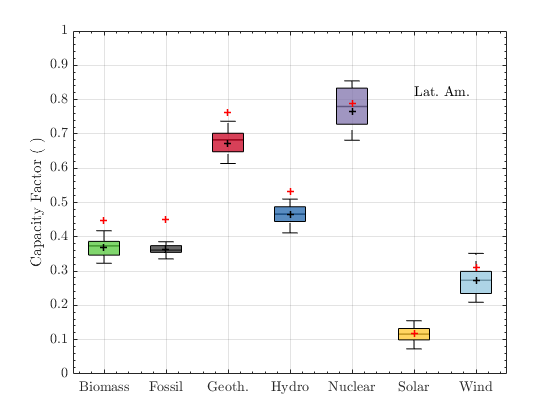

LatAm_B=[Mat_CF_Bio(:,5) Mat_CF_Fos(:,5) Mat_CF_Geo(:,5) Mat_CF_Hyd(:,5)...
    Mat_CF_Nuc(:,5) Mat_CF_Sol(:,5) Mat_CF_Win(:,5)];
LatAm_Mean_CF=[Mean_CF_Bio(5) Mean_CF_Fos(5) Mean_CF_Geo(5)...
    Mean_CF_Hyd(5) Mean_CF_Nuc(5) Mean_CF_Sol(5) Mean_CF_Win(5)];
LatAm_Mean_CF_W=[Mean_CF_W_Bio(5) Mean_CF_W_Fos(5) Mean_CF_W_Geo(5)...
    Mean_CF_W_Hyd(5) Mean_CF_W_Nuc(5) Mean_CF_W_Sol(5) Mean_CF_W_Win(5)];
LatAm_STD=[STD_CF_Bio(5) STD_CF_Fos(5) STD_CF_Geo(5) STD_CF_Hyd(5)...
    STD_CF_Nuc(5) STD_CF_Sol(5) STD_CF_Win(5)];


 
figure('Name','Box LatAm')
hold on
plot(LatAm_Mean_CF,'+k','LineWidth',1.5)
plot(LatAm_Mean_CF_W,'+r','LineWidth',1.5)
boxplot(LatAm_B,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorBR(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(LatAm_Mean_CF,'+k','LineWidth',1.5)
plot(LatAm_Mean_CF_W,'+r','LineWidth',1.5)
% xlabel('$$\mathrm{Source}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
% legend({'Mean','W.~Mean'},'Location','northeast','FontSize', 12,'NumColumns',1,...
%     'box','on','interpreter','latex')
text(6,0.82,'Lat.~Am.','Fontsize',14,'Interpreter','latex')
ylim([0 1])
set(gca, 'XTickLabel', legR);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

print('-dpng','-r400','LatAm_CF_B.png');

## MENA

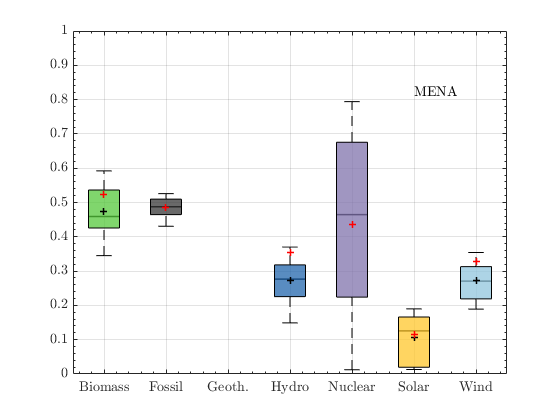

MENA_B=[Mat_CF_Bio(:,6) Mat_CF_Fos(:,6) Mat_CF_Geo(:,6) Mat_CF_Hyd(:,6)...
    Mat_CF_Nuc(:,6) Mat_CF_Sol(:,6) Mat_CF_Win(:,6)];
MENA_Mean_CF=[Mean_CF_Bio(6) Mean_CF_Fos(6) Mean_CF_Geo(6)...
    Mean_CF_Hyd(6) Mean_CF_Nuc(6) Mean_CF_Sol(6) Mean_CF_Win(6)];
MENA_Mean_CF_W=[Mean_CF_W_Bio(6) Mean_CF_W_Fos(6) Mean_CF_W_Geo(6)...
    Mean_CF_W_Hyd(6) Mean_CF_W_Nuc(6) Mean_CF_W_Sol(6) Mean_CF_W_Win(6)];
MENA_STD=[STD_CF_Bio(6) STD_CF_Fos(6) STD_CF_Geo(6) STD_CF_Hyd(6)...
    STD_CF_Nuc(6) STD_CF_Sol(6) STD_CF_Win(6)];


figure('Name','Box MENA')
hold on
plot(MENA_Mean_CF,'+k','LineWidth',1.5)
plot(MENA_Mean_CF_W,'+r','LineWidth',1.5)
boxplot(MENA_B,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorBR(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(MENA_Mean_CF,'+k','LineWidth',1.5)
plot(MENA_Mean_CF_W,'+r','LineWidth',1.5)
%xlabel('$$\mathrm{Source}$$','interpreter','latex')
%ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
% legend({'Mean','W.~Mean'},'Location','northeast','FontSize', 12,'NumColumns',1,...
%     'box','on','interpreter','latex')
text(6,0.82,'MENA','Fontsize',14,'Interpreter','latex')
ylim([0 1])
set(gca, 'XTickLabel', legR);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-dpdf','-r400','MENA_CF_B.pdf');
print('-dpng','-r400','MENA_CF_B.png');

## North America

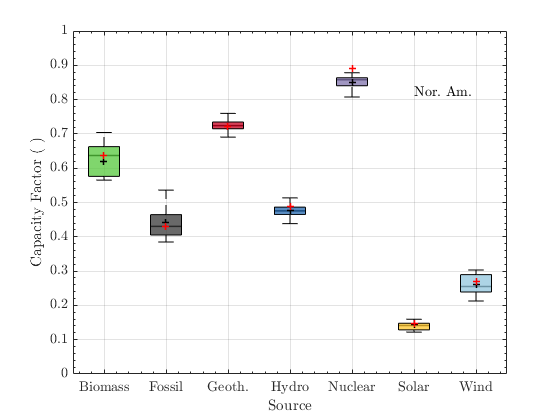

NorAm_B=[Mat_CF_Bio(:,7) Mat_CF_Fos(:,7) Mat_CF_Geo(:,7) Mat_CF_Hyd(:,7)...
    Mat_CF_Nuc(:,7) Mat_CF_Sol(:,7) Mat_CF_Win(:,7)];
NorAm_Mean_CF=[Mean_CF_Bio(7) Mean_CF_Fos(7) Mean_CF_Geo(7)...
    Mean_CF_Hyd(7) Mean_CF_Nuc(7) Mean_CF_Sol(7) Mean_CF_Win(7)];
NorAm_Mean_CF_W=[Mean_CF_W_Bio(7) Mean_CF_W_Fos(7) Mean_CF_W_Geo(7)...
    Mean_CF_W_Hyd(7) Mean_CF_W_Nuc(7) Mean_CF_W_Sol(7) Mean_CF_W_Win(7)];
NorAm_STD=[STD_CF_Bio(7) STD_CF_Fos(7) STD_CF_Geo(7) STD_CF_Hyd(7)...
    STD_CF_Nuc(7) STD_CF_Sol(7) STD_CF_Win(7)];

figure('Name','Box NorAm')
hold on
plot(NorAm_Mean_CF,'+k','LineWidth',1.5)
plot(NorAm_Mean_CF_W,'+r','LineWidth',1.5)
boxplot(NorAm_B,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorBR(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(NorAm_Mean_CF,'+k','LineWidth',1.5)
plot(NorAm_Mean_CF_W,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Source}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
%legend({'Mean','W.~Mean'},'Location','northeast','FontSize', 12,'NumColumns',1,...
%     'box','on','interpreter','latex')
text(6,0.82,'Nor.~Am.','Fontsize',14,'Interpreter','latex')
ylim([0 1])
set(gca, 'XTickLabel', legR);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
print('-dpng','-r400','NorAm_CF_B.png');

## Oceania

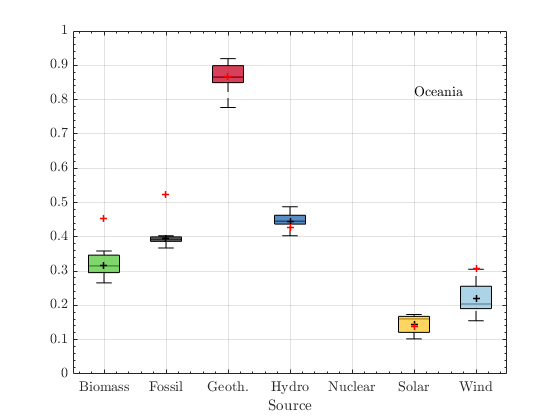

Oceania_B=[Mat_CF_Bio(:,8) Mat_CF_Fos(:,8) Mat_CF_Geo(:,8) Mat_CF_Hyd(:,8)...
    Mat_CF_Nuc(:,8) Mat_CF_Sol(:,8) Mat_CF_Win(:,8)];
Oceania_Mean_CF=[Mean_CF_Bio(8) Mean_CF_Fos(8) Mean_CF_Geo(8)...
    Mean_CF_Hyd(8) Mean_CF_Nuc(8) Mean_CF_Sol(8) Mean_CF_Win(8)];
Oceania_Mean_CF_W=[Mean_CF_W_Bio(8) Mean_CF_W_Fos(8) Mean_CF_W_Geo(8)...
    Mean_CF_W_Hyd(8) Mean_CF_W_Nuc(8) Mean_CF_W_Sol(8) Mean_CF_W_Win(8)];
Oceania_STD=[STD_CF_Bio(8) STD_CF_Fos(8) STD_CF_Geo(8) STD_CF_Hyd(8)...
    STD_CF_Nuc(8) STD_CF_Sol(8) STD_CF_Win(8)];



figure('Name','Box Oceania')
hold on
plot(Oceania_Mean_CF,'+k','LineWidth',1.5)
plot(Oceania_Mean_CF_W,'+r','LineWidth',1.5)
boxplot(Oceania_B,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorBR(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(Oceania_Mean_CF,'+k','LineWidth',1.5)
plot(Oceania_Mean_CF_W,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Source}$$','interpreter','latex')
%ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
%legend({'Mean','W.~Mean'},'Location','northeast','FontSize', 12,'NumColumns',1,...
   % 'box','on','interpreter','latex')
text(6,0.82,'Oceania','Fontsize',14,'Interpreter','latex')
ylim([0 1])
set(gca, 'XTickLabel', legR);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-dpdf','-r400','Oceania_CF_B.pdf');
print('-dpng','-r400','Oceania_CF_B.png');

## World

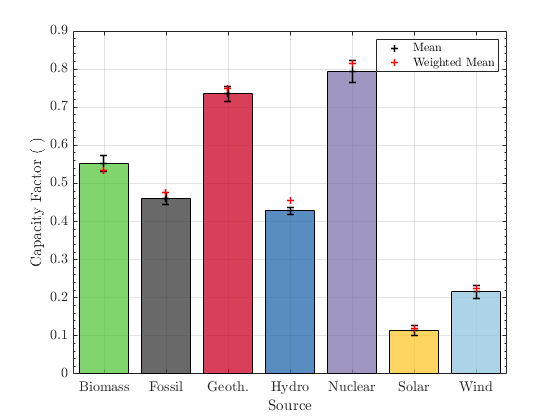

World_B=[Mat_CF_Bio(:,9) Mat_CF_Fos(:,9) Mat_CF_Geo(:,9) Mat_CF_Hyd(:,9)...
    Mat_CF_Nuc(:,9) Mat_CF_Sol(:,9) Mat_CF_Win(:,9)];
World_Mean_CF=[Mean_CF_Bio(9) Mean_CF_Fos(9) Mean_CF_Geo(9)...
    Mean_CF_Hyd(9) Mean_CF_Nuc(9) Mean_CF_Sol(9) Mean_CF_Win(9)];
World_Mean_CF_W=[Mean_CF_W_Bio(9) Mean_CF_W_Fos(9) Mean_CF_W_Geo(9)...
    Mean_CF_W_Hyd(9) Mean_CF_W_Nuc(9) Mean_CF_W_Sol(9) Mean_CF_W_Win(9)];
World_STD=[STD_CF_Bio(9) STD_CF_Fos(9) STD_CF_Geo(9) STD_CF_Hyd(9)...
    STD_CF_Nuc(9) STD_CF_Sol(9) STD_CF_Win(9)];

figure('Name','World Bar')
hold on
plot(X,World_Mean_CF,'+k','linewidth',1.5)
plot(World_Mean_CF_W,'+r','linewidth',1.5)
h=bar(X,World_Mean_CF);
errorbar(X,World_Mean_CF,World_STD,'+k','linewidth',1.5)
plot(World_Mean_CF,'+k','linewidth',1.5)
plot(World_Mean_CF_W,'+r','linewidth',1.5)
% Color
h.FaceColor = 'flat';
h.FaceAlpha=0.75;
h.CData(1,:) = Color(1,:);
h.CData(2,:) = Color(2,:);
h.CData(3,:) = Color(3,:);
h.CData(4,:) = Color(4,:);
h.CData(5,:) = Color(5,:);
h.CData(6,:) = Color(6,:);
h.CData(7,:) = Color(7,:);
legend({'Mean','Weighted Mean'},'Location','northeast','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
xlabel('$$\mathrm{Source}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
% print('-dpdf','-r400','World_CF.pdf');
print('-dpng','-r400','World_CF.png');

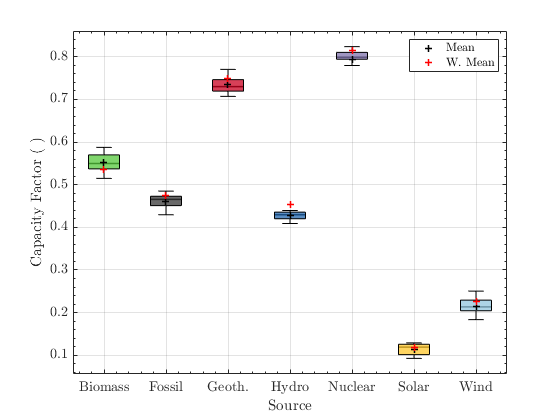


 figure('Name','Box World')
hold on
plot(World_Mean_CF,'+k','LineWidth',1.5)
plot(World_Mean_CF_W,'+r','LineWidth',1.5)
boxplot(World_B,'symbol','');

h = findobj(gca,'Tag','Box');
for j=1:length(h) 
patch(get(h(j),'XData'),get(h(j),'YData'),ColorBR(j,:),'FaceAlpha',.75);
end 
lines = findobj(gcf, 'type', 'line', 'Tag', 'Median');
set(lines, 'Color', 'k','LineWidth',1.5);
O = findobj(gcf,'tag','Outliers');
set(O,'MarkerSize',8,'LineWidth',1.5)
plot(World_Mean_CF,'+k','LineWidth',1.5)
plot(World_Mean_CF_W,'+r','LineWidth',1.5)
xlabel('$$\mathrm{Source}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
legend({'Mean','W.~Mean'},'Location','northeast','FontSize', 12,'NumColumns',1,...
    'box','on','interpreter','latex')
set(gca, 'XTickLabel', legR);
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')
print('-dpng','-r400','World_CF_B.png');

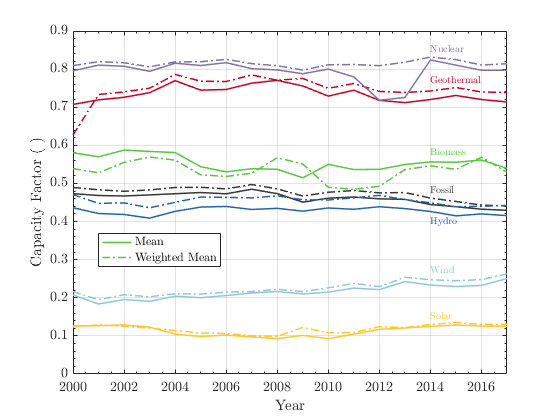

 
 figure('Name','CF Mean and Weighted')
 hold on
 plot(Year,CF_Bio(1,:),"Color",Color(1,:),'LineWidth',1.5)
 plot(Year,World_CF_W_Bio,'-.',"Color",Color(1,:),'LineWidth',1.5)
 plot(Year,CF_Fos(1,:),"Color",Color(2,:),'LineWidth',1.5)
 plot(Year,World_CF_W_Fos,'-.',"Color",Color(2,:),'LineWidth',1.5)
 plot(Year,CF_Geo(1,:),"Color",Color(3,:),'LineWidth',1.5)
 plot(Year,World_CF_W_Geo,'-.',"Color",Color(3,:),'LineWidth',1.5)
 plot(Year,CF_Hyd(1,:),"Color",Color(4,:),'LineWidth',1.5)
 plot(Year,World_CF_W_Hyd,'-.',"Color",Color(4,:),'LineWidth',1.5)
 plot(Year,CF_Nuc(1,:),"Color",Color(5,:),'LineWidth',1.5)
 plot(Year,World_CF_W_Nuc,'-.',"Color",Color(5,:),'LineWidth',1.5)
 plot(Year,CF_Sol(1,:),"Color",Color(6,:),'LineWidth',1.5)
 plot(Year,World_CF_W_Sol,'-.',"Color",Color(6,:),'LineWidth',1.5)
 plot(Year,CF_Win(1,:),"Color",Color(7,:),'LineWidth',1.5)
 plot(Year,World_CF_W_Win,'-.',"Color",Color(7,:),'LineWidth',1.5)
 xlabel('$$\mathrm{Year}$$','interpreter','latex')
ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
leg={'Bio.';'Bio.~W.'; ...
    'Fossil'; 'Fossil~W.';...
    'Geoth.';'Geoth.~W.';...
    'Hy+ro'; 'Hy+ro~W.'; ...
    'Nuclear'; 'Nuclear~W.';... 
    'Solar'; 'Solar~W.'; ...
    'Wind'; 'Wind~W.';};
legend({'Mean','Weighted Mean'},'Position',[0.26 0.38 0.05 0.05],'FontSize', 12,'NumColumns',1,...
    'interpreter','latex')
xlim([2000 2017])
ylim([0 0.9])
text(2014,.58,'Biomass','Color',Color(1,:),'Interpreter','latex')
text(2014,.48,'Fossil','Color',Color(2,:),'Interpreter','latex')
text(2014,.77,'Geothermal','Color',Color(3,:),'Interpreter','latex')
text(2014,.4,'Hydro','Color',Color(4,:),'Interpreter','latex')
text(2014,.85,'Nuclear','Color',Color(5,:),'Interpreter','latex')
text(2014,.15,'Solar','Color',Color(6,:),'Interpreter','latex')
text(2014,.27,'Wind','Color',Color(7,:),'Interpreter','latex')
% axis tight
box on
grid on
set(gca,'XMinorTick','on','YMinorTick','on')
set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex') 

 print('-dpng','-r400','World_H.png');

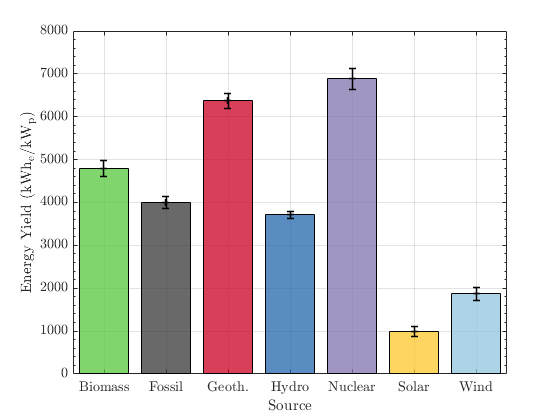

figure('Name','World Bar')
hold on
plot(X,World_Mean_CF*8670,'+k','linewidth',1.5)
h=bar(X,World_Mean_CF*8670);
errorbar(X,World_Mean_CF*8670,World_STD*8670,'+k','linewidth',1.5)
plot(World_Mean_CF*8670,'+k','linewidth',1.5)

% Color
h.FaceColor = 'flat';
h.FaceAlpha=0.75;
h.CData(1,:) = Color(1,:);
h.CData(2,:) = Color(2,:);
h.CData(3,:) = Color(3,:);
h.CData(4,:) = Color(4,:);
h.CData(5,:) = Color(5,:);
h.CData(6,:) = Color(6,:);
h.CData(7,:) = Color(7,:);
% legend({'Mean','Weighted Mean'},'Location','northeast','FontSize', 12,'NumColumns',1,...
%     'box','on','interpreter','latex')
xlabel('$$\mathrm{Source}$$','interpreter','latex')
% ylabel('$$\mathrm{Capacity~Factor~(~)}$$','interpreter','latex')
ylabel('Energy Yield ($\mathrm{kWh_e/kW_p}$)','Interpreter','latex')
box on
grid on
xtickangle(0)
set(gca,'XMinorTick','on','YMinorTick','on')
 set(gca,'Fontsize',14,'TickDir','in','FontWeight','normal','GridAlpha',0.13,...
     'LineWidth',0.2,'TickLength',[0.01 0.01],'TickLabelInterpreter','latex')

% print('-dpdf','-r400','World_CF.pdf');
% print('-dpng','-r400','World_CF.png');

## Make Table

% Here also make the table that for the regions
Af=[Africa_Mean_CF; Africa_Mean_CF_W];
Af=reshape(Af,1,14);
As=[Asia_Mean_CF; Asia_Mean_CF_W];
As=reshape(As,1,14);
Ac=[CIS_Mean_CF; CIS_Mean_CF_W];
Ac=reshape(Ac,1,14);
Ae=[Europe_Mean_CF; Europe_Mean_CF_W];
Ae=reshape(Ae,1,14);
Al=[LatAm_Mean_CF; LatAm_Mean_CF_W];
Al=reshape(Al,1,14);
Am=[MENA_Mean_CF; MENA_Mean_CF_W];
Am=reshape(Am,1,14);
An=[NorAm_Mean_CF; NorAm_Mean_CF_W];
An=reshape(An,1,14);
Ao=[Oceania_Mean_CF; Oceania_Mean_CF_W];
Ao=reshape(Ao,1,14);


A=[World_Mean_CF; World_Mean_CF_W];
A=reshape(A,1,14);
M=[Af;As;Ac;Ae;Al;Am;An;Ao;A];
L={'Africa','Asia','CIS','Europe','Latin Am.','MENA','North Am.','Oceania','World'};
Table_CF=[L',array2table(M)];
Table_CF.Properties.VariableNames={'Country','BM','BW','FM','FW','GM','GW','HM','HW','NM','NW','SM','SW','WM','WW'};
Table_CF

Table_CF = 9×15 table
       Country         BM         BW         FM         FW         GM         GW         HM         HW         NM         NW          SM          SW         WM         WW   
    _____________    _______    _______    _______    _______    _______    _______    _______    _______    _______    _______    ________    ________    _______    _______

    {'Africa'   }    0.32115    0.43169    0.30973    0.57363    0.56059     0.7418    0.44385    0.55071    0.79767   